This script uses analytical theory to fit experimental SAXS data of Polyimide-PEG random copolymers.

Load experiment data.

clear;
close all
addpath('functions/')
data = load('exp-data/PEG30undoped.csv');  % SAXS data with q in A^(-1)
                                           % 30wt ~= 16mol%
rm = 32.05; % estimate end-to-end distance of a "chemical monomer" in unit Angstrom
FA=0.165;    % equal chemical composition

TV = [22,40:20:180];  % temperature in degree C
TK = TV+273.15;       % temperature in Kelvin
q = data(:,1);
s = data(:,2:end);

Define a small q cutoff and estimate peak intensity S(q~=0).

% if PEG wt% = 0.30
qmin0 = 0.03803;
qminf = 0.04094;

iqmin0 = find(q==qmin0);
iqminf = find(q==qminf);
smin = mean(s(iqmin0:iqminf,:));
sminstd = std(1./s(iqmin0:iqminf,:));

Make a plot of structure factor.

% at which temperature?
Trange=1:9;
figure;hold

Current plot held


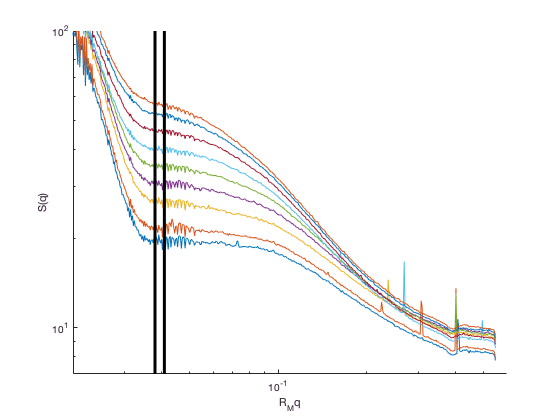

for T=Trange
    plot(q,s(:,T));
end
plot([qmin0,qmin0],[7,1e2],'k-','linewidth',3)
plot([qminf,qminf],[7,1e2],'k-','linewidth',3)

xlabel('R_Mq');ylabel('S(q)')
set(gca,'xscale','log');set(gca,'yscale','log');
xlim([0.02,0.6]);ylim([7,1e2]);

 Next plot temperature versus estimated inverse peak intensity. Theoretical estimate of ODT temperature is the x-intercept of the plot.

figure;hold;

Current plot held


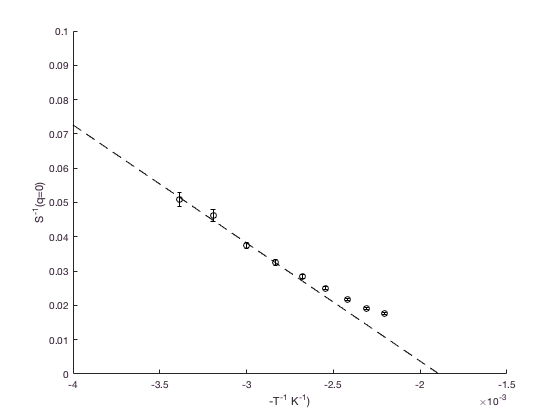

xp = -1./TK; %negative sign to account for temperature effects on SAXS intensity (degree of phase segregation)
yp = power(smin,-1);
errorbar(xp,yp,sminstd,'ko')
xlabel('-T^{-1} K^{-1})');ylabel('S^{-1}(q=0)')

% fit linear regression at q*=0
xfit = 1:3;  % linear fit regime at low Temperature
x = xp(xfit)';
X = [ones(length(x),1) x];
y = yp(xfit)';
b = X\y;
xp = linspace(-4,-1,100)*1e-3;
yp = b(2)*xp+b(1);
plot(xp,yp,'k--');
ylim([0,.1])

Plot analytical structure factor.

% polymer parameters
N=100;  % total of 100 monomers
NM=0.1; % each monomer has 0.1 Kuhn steps
LAM=0.50; % ideal random copolymer

% length parameters
RM=sqrt(r2wlc(NM));  % end-to-end distance of a monomers
K0=1e-1;  % minimum wavevector
KF=1e2;   % maximum wavevector
NK=101;  % number of wavevectors
K=transpose(logspace(log10(K0),log10(KF),NK))/RM;

% evaluate s2inv
[SINV]=s2invwlc(N,NM,FA,LAM,K);
[KS,SS]=kmaxwlc(N,NM,FA,LAM);
CHIS=0.5*SS*NM;

CHIV=linspace(0.1,0.9,9);   % Flory-Huggins parameter in units of CHIS (ODT CHI)
figure;hold

Current plot held


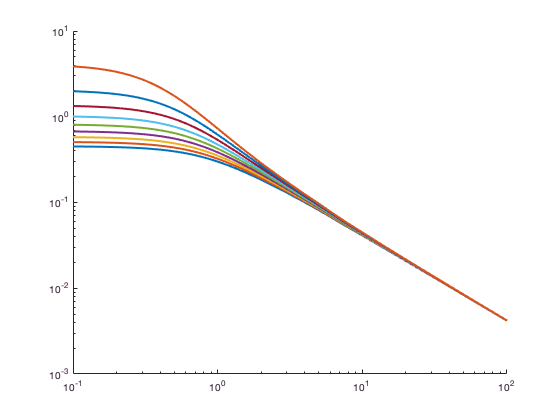

for CHI=CHIV
    plot(RM*K,1./(-2*CHI*CHIS+SINV*NM),'-','LineWidth',2)
end
set(gca,'xscale','log');set(gca,'yscale','log');

Plot theoretical prediction of temperature versus estimated inverse peak intensity.

% CHIV=linspace(0.1,1.1,9);   % Flory-Huggins parameter in units of CHIS (ODT CHI)
% Smin = power(-2*CHIV*CHIS+1/(FA*(1-FA)),-1);  % zero q analytical structure factor
% figure;plot(CHIV,1./Smin);ylim([0,7])
% xlabel('\chi');ylabel('S^{-1}(q=0)')

Start fitting analytical S(q) to experimental data.

% define fitting range
qf = q(iqmin0:end);
    
% fit to structure factor
x0 = [40,0.5,0.5];  %initial fit guess, % x(1) = intensity scale, x(2) = CHI, x(3) = LAM
SNf=zeros(9,1);
CHIf=zeros(9,1);
LAMf=zeros(9,1);
Sfit=zeros(length(qf),9);

Current plot held


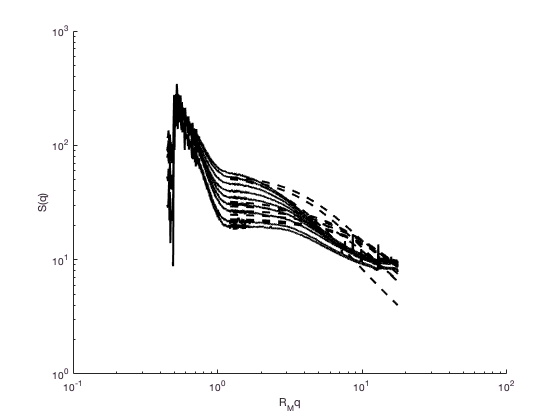


Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 5 (the selected value).


Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 5 (the selected value).


Solver stopped prematurely.

lsqcurvefit stopped beca

for IT=1:9
    sf = s(iqmin0:end,IT);
    
    % start fitting
    [x,Sfit(:,IT)]=saxsfit(qf,sf,x0,N,NM,FA,rm,CHIS);

    % save to results
    SNf(IT)=x(1);
    CHIf(IT)=x(2);
    LAMf(IT)=x(3);
end

figure;hold

Current plot held


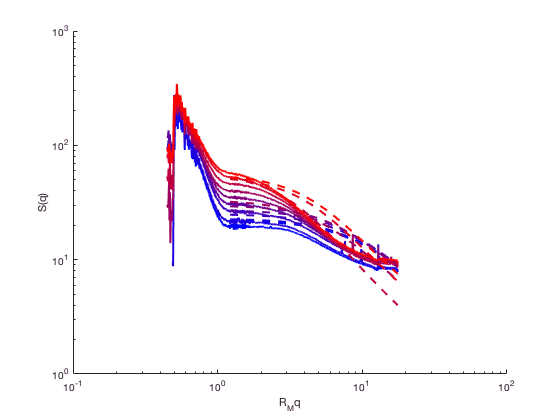

for IT=1:9
    col = (IT-1)/(9-1);
    
    % plot experimental and fits
    plot(q*rm,s(:,IT),'-','LineWidth',2,'color',[col 0 1-col]) % experiment data
    plot(qf*rm,Sfit(:,IT),'--','LineWidth',2,'color',[col 0 1-col]) % theoretical fit
end
xlabel('R_Mq');ylabel('S(q)');
set(gca,'xscale','log');set(gca,'yscale','log');

%title(strcat('T=',num2str(TK(IT)),'K'))